dt=1/1000;
t = 0:dt:0.5;
u1 = sin(2*pi*50*t);
u2 = sin(2*pi*100*t);
u3 = 0*sin(2*pi*75*t);

u = u1+u2+u3;
M=300;
H = hankel(u(1:M),u(M:end));

[U,S,V]=svd(H);

rr=rank(H)

rr = 4

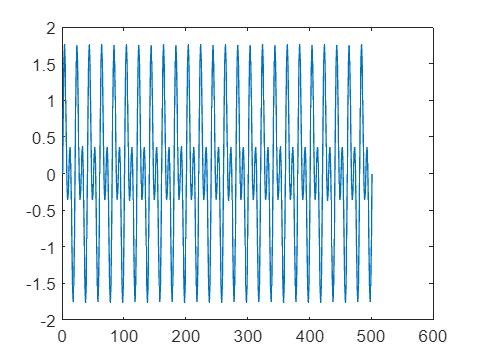

figure; plot(u)

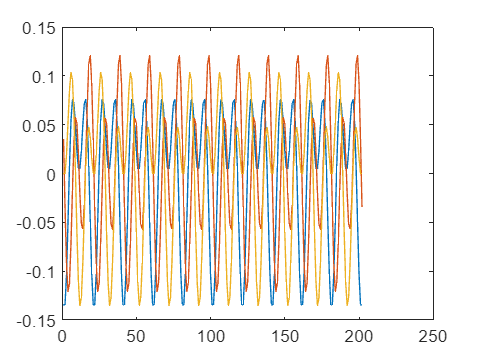

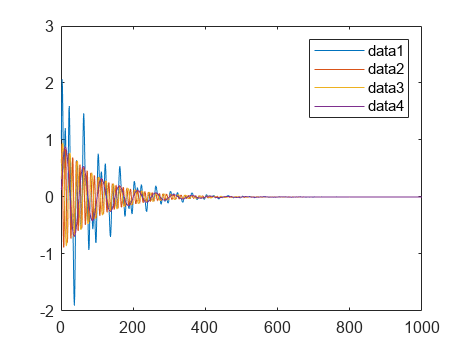

hankelSeries =     1.0120    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    0.0000
    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    

ar_model =
Discrete-time AR model: A(z)y(t) = e(t)                                                                            
  A(z) = 1 - 7.126 z^-1 + 22.99 z^-2 - 43.79 z^-3 + 53.84 z^-4 - 43.75 z^-5 + 22.95 z^-6 - 7.107 z^-7 + 0.9965 z^-8
                                                                                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                          
Estimated using AR ('fb/now') on time domain data "train_series".
Fit to estimation data: 100%                                     
FPE: 5.668e-11, MSE: 5.578e-11                                   
 


    "Prediction using full time series (no noise): -9.5476e-05"
    "Prediction using full time series (no noise): -9.9543e-05"
    "Prediction using full time series (no noise): -8.2706e-05"
    "Prediction using full time series (no noise): -4.6597e-05"
    "Prediction using full time series (no noise): 6.8875e-07"



    "Ground truth: -9.5479e-05"
    "Ground truth: -9.9563e-05"
    "Ground truth: -8.2793e-05"
    "Ground truth: -4.6871e-05"
    "Ground truth: 6.9033e-19"




%kunnen we dmv de values van V en die individueel gebruiken om het volgende
%punt te voorspelen mogelijk een betere voorspelling doen dan als we het
%gecombineerde gebruiken om het volgende punt te voorspellen?
figure; plot(V(:,1));
hold all; plot(V(:,2));
plot(V(:,3))

clear all;
format long;

% Parameters
N = 500;  % Number of points in the time series
num_predict = 1;
L = floor((N-1) / 2);
num_experiments = 100;  % Number of experiments to perform
optimal_order = 20;  % Set a fixed optimal order for simplicity

% Generate sinusoidal signals
t = (1:N)';

option = 3;

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * 0.1 * t);
base_signal2 = sin(2 * pi * 0.05 * t);
base_signal3 = sin(2 * pi * 0.02 * t);

% Apply selected option
switch option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');

% Ground truth for point 100
ground_truths = zeros(num_experiments,1);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_SVD = zeros(num_experiments, 1);

% Visualize the singular values of the Hankel matrix
H2D = hankel(time_series(1:L), time_series(L:end-1));
[U, S, V] = svd(H2D, 'econ');
singular_values = diag(S);

rank(H2D)

ans =      7


figure;
plot(singular_values, 'o-');
title('Singular Values of the Hankel Matrix');
xlabel('Index');
ylabel('Singular Value');
grid on;

rel_error_full = zeros(num_experiments,1);
rel_error_SVD = zeros(num_experiments,1);
norm_error_full = zeros(num_experiments,1);
norm_error_SVD = zeros(num_experiments,1);


% Perform the experiment
for exp = 1:num_experiments 
    if mod(exp,10)==0
        disp("iter "+exp);
    end
    % Add noise (for testing with noise, if needed)
    %noisy_series = time_series;  % No noise added in this case
    noisy_series = time_series+ randn(N, 1) * 0.1;  % No noise added in this case

    ground_truths(exp) = noisy_series(end);


    training_series = noisy_series(1:N-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_series, num_predict);
    predictions_full(exp) = pred_full(end);

    % 2. Decomposition using Hankel matrix (SVD)
    %H2Dzeros = hankel(noisy_series(1:N-1));
    H2Dzeros = hankel(noisy_series(1:L),noisy_series(L:end-1));
    [U, S, V] = svd(H2Dzeros, 'econ');    

    num_components = 7;
    c = zeros(L, N-L, num_components);
    pred_components = zeros(num_components, 1);

    
    figure;
    
    %plot(time_series)
    for comp = 1:num_components
        %tensor for holding all components (which are matrices)
        matrix_component = U(:,comp)*S(comp,comp)*V(:,comp)';

        % Convert component matrix back to time series by averaging along anti-diagonals
        component_series = serialize2D(matrix_component);

        %hold on;
        %plot(component_series);
        model_comp = ar(component_series, optimal_order);
        pred_comp = forecast(model_comp, component_series, num_predict);
        pred_components(comp) = pred_comp(end);
    end
    %legend({'Original', 'c1', 'c2', 'c3', 'c4', 'c5', 'c6', 'c7'});
    %hold off;

    predictions_SVD(exp) = sum(pred_components);

    rel_error_full(exp) = abs(predictions_full(exp)-ground_truths(exp))/abs(ground_truths(exp));
    rel_error_SVD(exp) = abs(predictions_SVD(exp)-ground_truths(exp))/abs(ground_truths(exp));
    norm_error_full(exp) = norm(predictions_full(exp),2)/norm(ground_truths(exp),2);
    norm_error_SVD(exp) = norm(predictions_SVD(exp),2)/norm(ground_truths(exp),2);
end

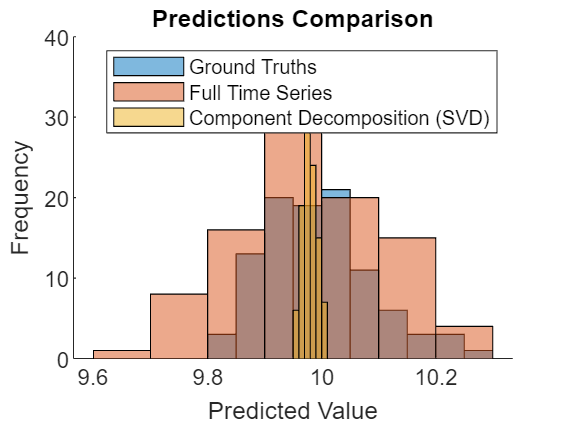

figure;
hold on;
histogram(ground_truths, 'FaceAlpha', 0.5, 'DisplayName', 'Ground Truths');
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
legend;
hold off;

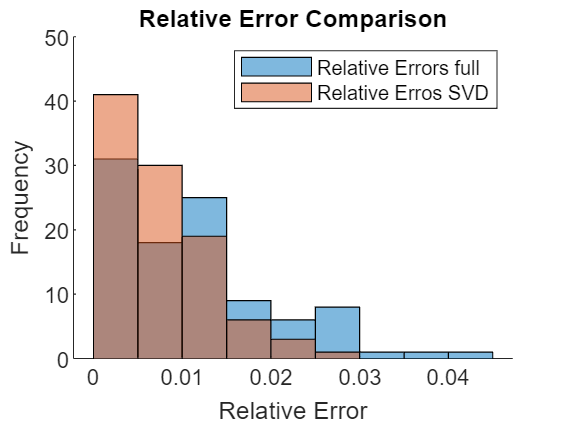


figure;
hold on;
histogram(rel_error_full, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Errors full');
histogram(rel_error_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Erros SVD');
%histogram(predictions_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Relative Error Comparison');
xlabel('Relative Error');
ylabel('Frequency');
legend;
hold off;

summary

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: "+mean(predictions_full)+ ...
    ", SD: "+std(predictions_full)+ ...
    ", RMSE: "+rmse(predictions_full,ground_truths)+ ...
    ", MRE: "+mean(rel_error_full)+ ...
    ", MRSE: "+mean(norm_error_full));

Mean: 9.9787, SD: 0.1235, RMSE: 0.14697, MRE: 0.011517, MRSE: 0.99851



errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full);mean(norm_error_full)];

disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: "+mean(predictions_SVD)+ ...
    ", SD: "+std(predictions_SVD)+ ...
    ", RMSE: "+rmse(predictions_SVD,ground_truths)+ ...
    ", MRE: "+mean(rel_error_SVD)+ ...
    ", MRSE: "+mean(norm_error_SVD));

Mean: 9.9793, SD: 0.012813, RMSE: 0.094576, MRE: 0.0074251, MRSE: 0.99858



errors_SVD = [mean(predictions_SVD);std(predictions_SVD);rmse(predictions_SVD,ground_truths);mean(rel_error_SVD);mean(norm_error_SVD)];



## Tensor vs full

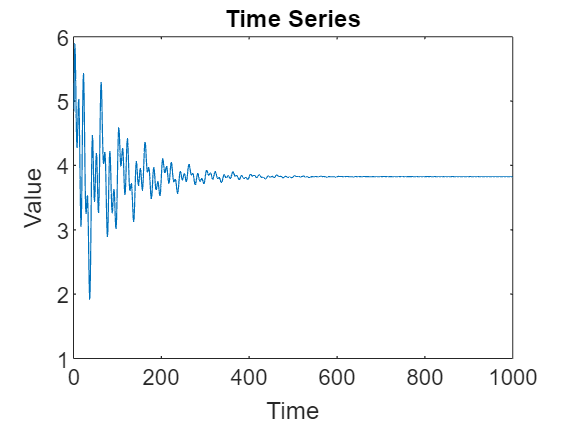

clear all;
format long;
addpath('./tensorlab/');

% Parameters
N = 1000;  % Number of points in the time series
num_predict = 1;
num_experiments = 10;  % Number of experiments to perform
optimal_order = 10;  % Set a fixed optimal order for simplicity for AR

% Generate sinusoidal signals
t = (1:N)';

option = 3;

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * 0.1 * t);
base_signal2 = sin(2 * pi * 0.05 * t);
base_signal3 = sin(2 * pi * 0.02 * t);

% Apply selected option
switch option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Ground truth for final point
ground_truths = zeros(num_experiments,1);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_CPD = zeros(num_experiments, 1);

rel_error_full = zeros(num_experiments,1);
norm_error_full = zeros(num_experiments,1);
rel_error_CPD = zeros(num_experiments,1);
norm_error_CPD = zeros(num_experiments,1);

% Perform the experiment
for exp = 1:num_experiments 
    if mod(exp,1)==0
        disp("iter "+exp);
    end
    % Add noise (for testing with noise)
    %noisy_series = time_series;  % No noise added in this case

    ground_truths(exp) = time_series(end); %keep this as the truth without the noise
    noisy_series = time_series + randn(N, 1) * 0.1;  % No noise added in this case

    training_series = noisy_series(1:N-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(training_series, optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_series, num_predict);
    predictions_full(exp) = pred_full(end);

    % 2. Decomposition using Hankel Tensor (CPD)
    predictions_CPD(exp) = ar_cpd(training_series,num_predict,optimal_order,7);

    rel_error_full(exp) = abs(predictions_full(exp)-ground_truths(exp))/abs(ground_truths(exp));
    norm_error_full(exp) = norm(predictions_full(exp),2)/norm(ground_truths(exp),2);
    rel_error_CPD(exp) = abs(predictions_CPD(exp)-ground_truths(exp))/abs(ground_truths(exp));
    norm_error_CPD(exp) = norm(predictions_CPD(exp),2)/norm(ground_truths(exp),2);
    %}
end

iter 1
iter 2
iter 3
iter 4
iter 5
iter 6
iter 7
iter 8
iter 9
iter 10


disp("Done!");

Done!


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: "+mean(predictions_full)+ ...
    ", SD: "+std(predictions_full)+ ...
    ", RMSE: "+rmse(predictions_full,ground_truths)+ ...
    ", MRE: "+mean(rel_error_full)+ ...
    ", MRSE: "+mean(norm_error_full));

Mean: 3.7916, SD: 0.088778, RMSE: 0.090604, MRE: 0.021266, MRSE: 0.99127



errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full);mean(norm_error_full)];

disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp("Mean: "+mean(predictions_CPD)+ ...
    ", SD: "+std(predictions_CPD)+ ...
    ", RMSE: "+rmse(predictions_CPD,ground_truths)+ ...
    ", MRE: "+mean(rel_error_CPD)+ ...
    ", MRSE: "+mean(norm_error_CPD));

Mean: 3.8269, SD: 0.01201, RMSE: 0.011555, MRE: 0.0026757, MRSE: 1.0005



errors_CPD = [mean(predictions_CPD);std(predictions_CPD);rmse(predictions_CPD,ground_truths);mean(rel_error_CPD);mean(norm_error_CPD)];

## Tensor vs full hankel variations

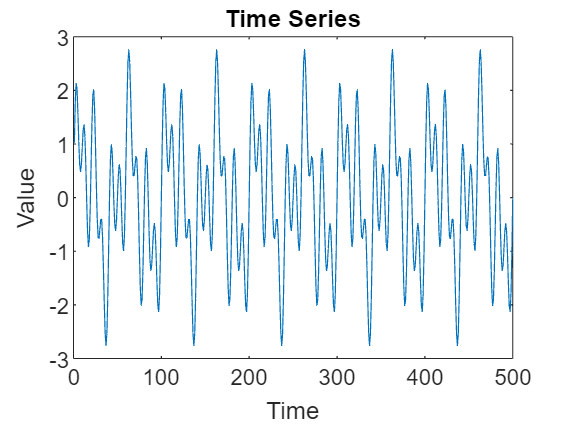

clear all;
format long;
addpath('./tensorlab/');

% Parameters
N = 500;  % Number of points in the time series
num_predict = 1;
num_experiments = 5;  % Number of experiments to perform
max_hankel_iter = 10; % Number of different hankel dimensions to try
optimal_order = 10;  % Set a fixed optimal order for simplicity

% Generate sinusoidal signals
t = (1:N)';

option = 1;

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * 0.1 * t);
base_signal2 = sin(2 * pi * 0.05 * t);
base_signal3 = sin(2 * pi * 0.02 * t);

% Apply selected option
switch option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Ground truth for point 100
ground_truths = zeros(num_experiments,1);


errors_over_hankel_full = zeros(6,max_hankel_iter);
errors_over_hankel_CPD = zeros(6,max_hankel_iter);

for dtrial = 1:max_hankel_iter
    
    fhdim = dtrial*10;
    disp("Hankel dimensions: "+fhdim+"x"+fhdim+"x"+(length(time_series)-num_predict-2*fhdim+2));
    
    % Prepare storage for predictions
    predictions_full = zeros(num_experiments, 1);
    predictions_CPD = zeros(num_experiments, 1);

    rel_error_full = zeros(num_experiments,1);
    norm_error_full = zeros(num_experiments,1);
    rel_error_CPD = zeros(num_experiments,1);
    norm_error_CPD = zeros(num_experiments,1);

    % Perform the experiment
    for exp = 1:num_experiments 
        if mod(exp,5)==0
            disp("iter "+exp);
        end
        % Add noise (for testing with noise, if needed)
        %noisy_series = time_series;  % No noise added in this case

        ground_truths(exp) = time_series(end); %keep this as the truth without the noise
        noisy_series = time_series+ randn(N, 1) * 0.1;  % No noise added in this case
    
        training_series = noisy_series(1:N-num_predict);
        
        % 1. Full time series prediction using AR model
        model_full = ar(training_series, optimal_order);  % AR(optimal_order) model
        pred_full = forecast(model_full, training_series, num_predict);
        predictions_full(exp) = pred_full(end);
    
        % 2. Decomposition using Hankel Tensor (CPD)
        L = fhdim+5;
        M = fhdim;
    
        %H2D = hankel(training_series(1:L),training_series(L:end));
        H3D = hankelize(training_series, 'Sizes', [L, M]);
        %disp("rank "+rankest(H3D));

        % Compute CPD
        R = 10; % Number of components
        [fac,~] = cpd(H3D, R);
        
        %low_rank_tensor = cpdgen(fac);
    
        %tensor_series = serialize3D(low_rank_tensor);
    
        pred_tcomponents = zeros(R, 1);
    

        for tcomp = 1:R
            tensor_component = cpdgen({fac{1}(:,tcomp),fac{2}(:,tcomp),fac{3}(:,tcomp)});
            
            % Reconstruct time series data
            tensor_series = serialize3D(tensor_component);
            
            model_tcomp = ar(tensor_series, optimal_order);
            pred_tcomp = forecast(model_tcomp, tensor_series, num_predict);
            pred_tcomponents(tcomp) = pred_tcomp(end-num_predict+1);
        end

        
        %{
        model_tcomp = ar(tensor_series, optimal_order);
        pred_tcomp = forecast(model_tcomp, tensor_series, num_predict);
    	pred_tcomponents = pred_tcomp(end-num_predict+1);
        %}

            
    
        predictions_CPD(exp) = sum(pred_tcomponents);
        %predictions_CPD(exp) = pred_tcomponents;
    
        rel_error_full(exp) = abs(predictions_full(exp)-ground_truths(exp))/abs(ground_truths(exp));
        norm_error_full(exp) = norm(predictions_full(exp),2)/norm(ground_truths(exp),2);
        rel_error_CPD(exp) = abs(predictions_CPD(exp)-ground_truths(exp))/abs(ground_truths(exp));
        norm_error_CPD(exp) = norm(predictions_CPD(exp),2)/norm(ground_truths(exp),2);
        %}
    end
    disp("Done!");
    errors_over_hankel_full(:,dtrial) = [fhdim;mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full);mean(norm_error_full)];
    errors_over_hankel_CPD(:,dtrial) = [fhdim;mean(predictions_CPD);std(predictions_CPD);rmse(predictions_CPD,ground_truths);mean(rel_error_CPD);mean(norm_error_CPD)];

end

Hankel dimensions: 10x10x481


iter 5


Done!


Hankel dimensions: 20x20x461


iter 5


Done!


Hankel dimensions: 30x30x441


iter 5


Done!


Hankel dimensions: 40x40x421


iter 5


Done!


Hankel dimensions: 50x50x401


iter 5


Done!


Hankel dimensions: 60x60x381


iter 5


Done!


Hankel dimensions: 70x70x361


iter 5


Done!


Hankel dimensions: 80x80x341


iter 5


Done!


Hankel dimensions: 90x90x321


iter 5


Done!


Hankel dimensions: 100x100x301


iter 5


Done!


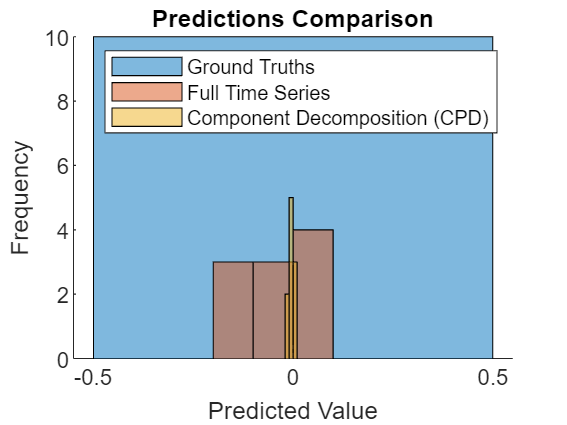

figure;
hold on;
histogram(ground_truths, 'FaceAlpha', 0.5, 'DisplayName', 'Ground Truths');
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_CPD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (CPD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
legend;
hold off;

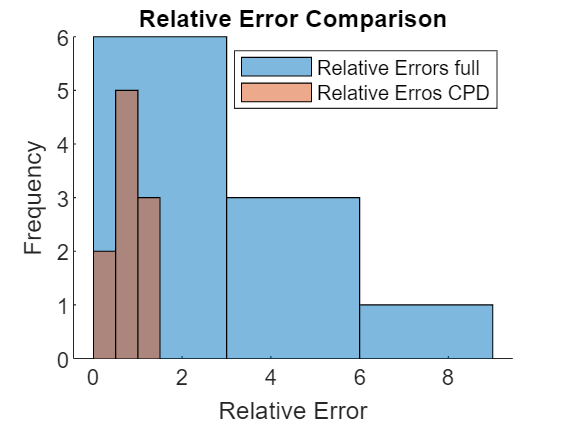


figure;
hold on;
histogram(rel_error_full, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Errors full');
histogram(rel_error_CPD, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Erros CPD');
%histogram(predictions_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Relative Error Comparison');
xlabel('Relative Error');
ylabel('Frequency');
legend;
hold off;

Summary

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: "+mean(predictions_full)+ ...
    ", SD: "+std(predictions_full)+ ...
    ", RMSE: "+rmse(predictions_full,ground_truths)+ ...
    ", MRE: "+mean(rel_error_full)+ ...
    ", MRSE: "+mean(norm_error_full));

Mean: -0.029901, SD: 0.10137, RMSE: 0.095468, MRE: 12062180036964.46, MRSE: 12062180036964.26



errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full);mean(norm_error_full)];

disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp("Mean: "+mean(predictions_CPD)+ ...
    ", SD: "+std(predictions_CPD)+ ...
    ", RMSE: "+rmse(predictions_CPD,ground_truths)+ ...
    ", MRE: "+mean(rel_error_CPD)+ ...
    ", MRSE: "+mean(norm_error_CPD));

Mean: 0.60009, SD: 1.9614, RMSE: 1.8542, MRE: 136107001996542.2, MRSE: 136107001996542



errors_CPD = [mean(predictions_CPD);std(predictions_CPD);rmse(predictions_CPD,ground_truths);mean(rel_error_CPD);mean(norm_error_CPD)];


A bit more stats on the CPD hankel dimensions ar on individual components

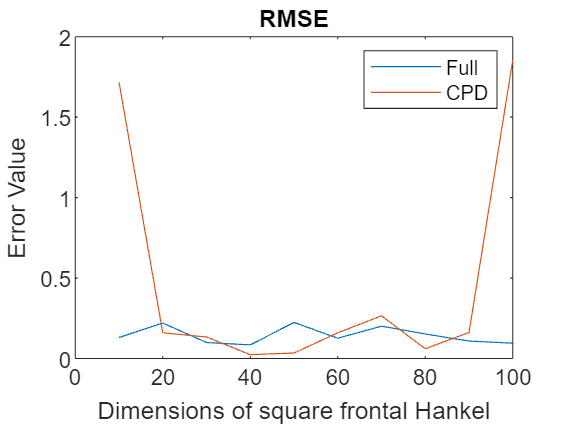

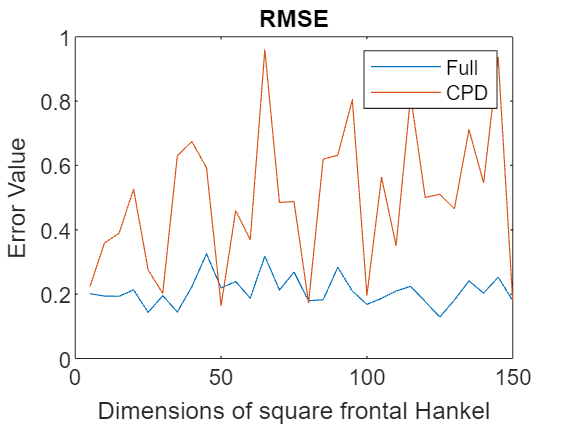

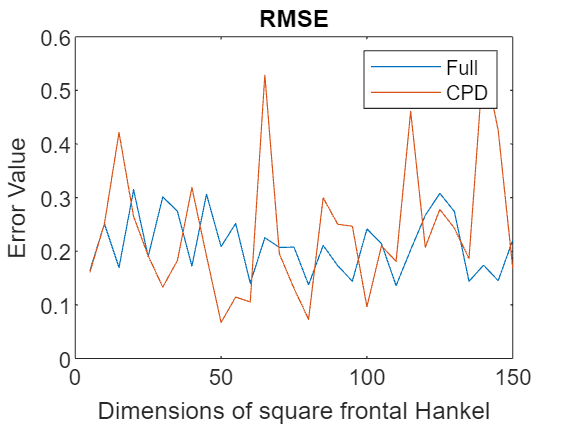

ans =    0.212609992933927


ans =    0.238110713897482


figure;

plot(errors_over_hankel_full(1,:),errors_over_hankel_full(4,:));

hold on;
plot(errors_over_hankel_CPD(1,:),errors_over_hankel_CPD(4,:));

% Set the title and labels
title('RMSE');
xlabel('Dimensions of square frontal Hankel');
ylabel('Error Value');

% Add legend
legend({"Full", "CPD"});

hold off;

## Full AR, SVD, CPD, MLSVD

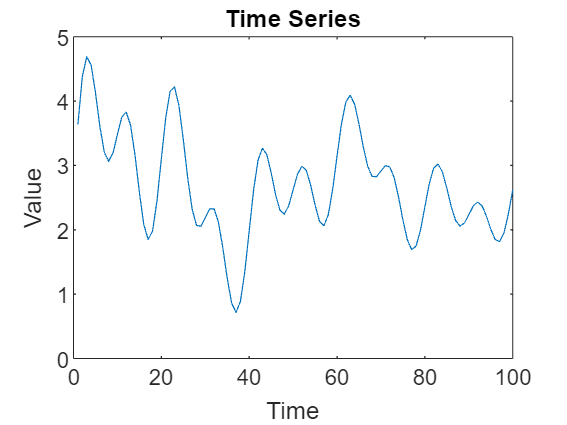

clear all;
format long;
addpath('./tensorlab/');

% Parameters
N = 100;  % Number of points in the time series
num_predict = 1;
num_experiments = 10;  % Number of experiments to perform
optimal_order = 10;  % Set a fixed optimal order for simplicity for AR

% Generate sinusoidal signals
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * 0.1 * t);
base_signal2 = sin(2 * pi * 0.05 * t);
base_signal3 = sin(2 * pi * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Ground truth for final point
ground_truths = zeros(num_predict, num_experiments);

% Prepare storage for predictions
predictions_full = zeros(num_predict, num_experiments);
rel_error_full = zeros(num_predict, num_experiments);
norm_error_full = zeros(num_predict, num_experiments);

predictions_SVD = zeros(num_predict, num_experiments);
rel_error_SVD = zeros(num_predict, num_experiments);
norm_error_SVD = zeros(num_predict, num_experiments);

predictions_CPD = zeros(num_predict, num_experiments);
rel_error_CPD = zeros(num_predict, num_experiments);
norm_error_CPD = zeros(num_predict, num_experiments);

predictions_mlsvd = zeros(num_predict, num_experiments);
rel_error_mlsvd = zeros(num_predict, num_experiments);
norm_error_mlsvd = zeros(num_predict, num_experiments);

% Perform the experiment
for exp = 1:num_experiments 
    if mod(exp,1)==0
        disp("iter "+exp);
    end
    
    ground_truths(:,exp) = time_series(end-num_predict+1:end);    
    
    % Add noise (for testing with noise)
    noisy_series = time_series + noise_option*(randn(N, 1) * 0.4);

    training_series = noisy_series(1:end-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(training_series, optimal_order);  % AR(optimal_order) model
    predictions_full(:,exp) = forecast(model_full, training_series, num_predict);

    % 2. Decomposition using Hankel Matrix (SVD)
    predictions_SVD(:,exp) = ar_svd(training_series,num_predict,optimal_order,7);

    % 3. Decomposition using Hankel Tensor (CPD)
    predictions_CPD(:,exp) = ar_cpd(training_series,num_predict,optimal_order,7);

    % 4. Decomposition using Hankel Tensor (MLSVD)
    predictions_mlsvd(:,exp) = ar_mlsvd(training_series,num_predict,optimal_order,0.2);

    % 5. Error calculations
    rel_error_full(:,exp) = abs(predictions_full(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_full(:,exp) = norm(predictions_full(:,exp),2)./norm(ground_truths(:,exp),2);

    rel_error_SVD(:,exp) = abs(predictions_SVD(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_SVD(:,exp) = norm(predictions_SVD(:,exp),2)./norm(ground_truths(:,exp),2);

    rel_error_CPD(:,exp) = abs(predictions_CPD(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_CPD(:,exp) = norm(predictions_CPD(:,exp),2)./norm(ground_truths(:,exp),2);
   
    rel_error_mlsvd(:,exp) = abs(predictions_mlsvd(:,exp)-ground_truths(:,exp))./abs(ground_truths(:,exp));
    norm_error_mlsvd(:,exp) = norm(predictions_mlsvd(:,exp),2)./norm(ground_truths(:,exp),2);
end

iter 1
iter 2
iter 3
iter 4
iter 5
iter 6
iter 7
iter 8
iter 9
iter 10


disp("Done!");

Done!



% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: "+mean(predictions_full,2)+ ...
    ", SD: "+std(predictions_full,0,2)+ ...
    ", RMSE: "+rmse(predictions_full,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_full,2)+ ...
    ", MRSE: "+mean(norm_error_full,2));

Mean: 2.4985, SD: 0.22231, RMSE: 0.24475, MRE: 0.081892, MRSE: 0.95265



errors_full = [mean(predictions_full,2),std(predictions_full,0,2),rmse(predictions_full,ground_truths,2),mean(rel_error_full,2),mean(norm_error_full,2)]';

disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: "+mean(predictions_SVD,2)+ ...
    ", SD: "+std(predictions_SVD,0,2)+ ...
    ", RMSE: "+rmse(predictions_SVD,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_SVD,2)+ ...
    ", MRSE: "+mean(norm_error_SVD,2));

Mean: 2.5372, SD: 0.13376, RMSE: 0.153, MRE: 0.045444, MRSE: 0.96741



errors_SVD = [mean(predictions_SVD,2),std(predictions_SVD,0,2),rmse(predictions_SVD,ground_truths,2),mean(rel_error_SVD,2),mean(norm_error_SVD,2)]';


disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp("Mean: "+mean(predictions_CPD,2)+ ...
    ", SD: "+std(predictions_CPD,0,2)+ ...
    ", RMSE: "+rmse(predictions_CPD,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_CPD,2)+ ...
    ", MRSE: "+mean(norm_error_CPD,2));

Mean: 1.893, SD: 0.2098, RMSE: 0.75637, MRE: 0.27823, MRSE: 0.72177



errors_CPD = [mean(predictions_CPD,2),std(predictions_CPD,0,2),rmse(predictions_CPD,ground_truths,2),mean(rel_error_CPD,2),mean(norm_error_CPD,2)]';

disp('Component Decomposition Predictions (MLSVD):');

Component Decomposition Predictions (CPD):


disp("Mean: "+mean(predictions_mlsvd,2)+ ...
    ", SD: "+std(predictions_mlsvd,0,2)+ ...
    ", RMSE: "+rmse(predictions_mlsvd,ground_truths,2)+ ...
    ", MRE: "+mean(rel_error_mlsvd,2)+ ...
    ", MRSE: "+mean(norm_error_mlsvd,2));

Mean: 2.4326, SD: 0.57009, RMSE: 0.57328, MRE: 0.1813, MRSE: 0.92751



errors_CPD = [mean(predictions_mlsvd,2),std(predictions_mlsvd,0,2),rmse(predictions_mlsvd,ground_truths,2),mean(rel_error_mlsvd,2),mean(norm_error_mlsvd,2)]';